% AAE 421 HW 4 Problem 3
% Tomoki Koike
close all; clear all; clc;
set(groot, 'defaulttextinterpreter','latex');
set(groot, 'defaultAxesTickLabelInterpreter','latex');
set(groot, 'defaultLegendInterpreter','latex');
fdir = "C:\Users\Tomo\Desktop\studies\2020-Fall\AAE421\matlab\output\hw4";
addpath(genpath("C:\Users\Tomo\Desktop\studies\2020-Fall\AAE421\matlab\rootlocus"));

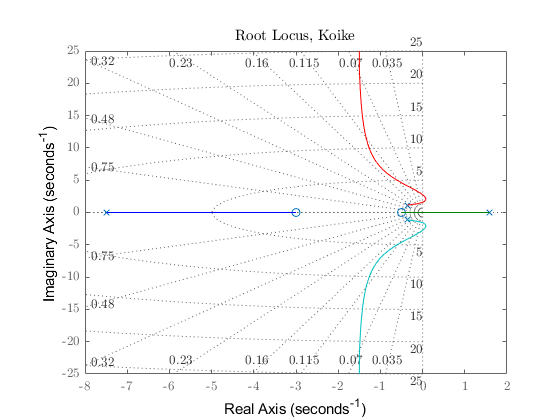

% RL

num = 11.0*conv([1, 0.5], [1, 3.0]);
den = conv([1, 0.72, 1.44], [1, 5.9, -11.9]);
L = tf(num, den);
% Plot
fig1 = figure(1);
    rlocus(L)
    title('Root Locus, Koike','interpreter','Latex')
    sgrid

saveas(fig1, fullfile(fdir, 'p3_RL.png'));

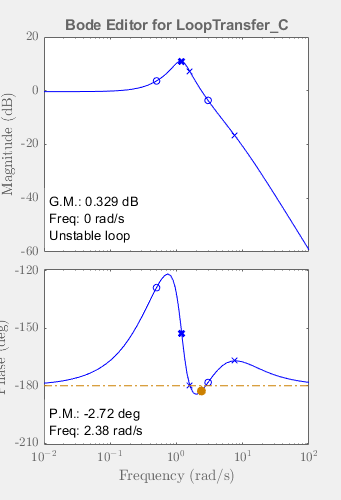

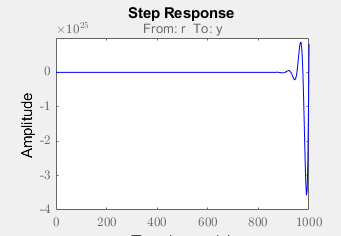

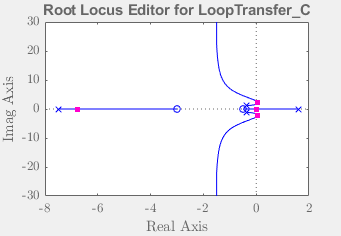

% Gain for stability
controlSystemDesigner(L);